# Comparison of Linear Discriminant Analysis Algorythm: Standard Formula vs Sphering the Data

Linear discriminant analysis is a simple linear method for solving categorization problems. There is a very well known formula for categorizing data based upon the statistics of the underlying data.

$G\left(x\right)={\textrm{argmax}}_k \delta_k \left(x\right)$,

for $\delta_k \left(x\right)=x^T \Sigma^{-1} \mu_k -\frac{1}{2}\mu_k^T \Sigma^{-1} \mu_k +\log \left(\pi_k \right)$.

Using a process called sphering the data this can be simplified to a simpler form. Then the classification process goes as follows, for each $x$ (that has been mapped into the spherised space) classify it according to the nearest centroids of the classifications with some punishment term based on the $\pi_k$ term.

There are two obvious questions that follow from these two methods.

- Do they give the same model?

- Do they run in different amounts of time, both at training and inference time?

The answer to 1 is easy in the theoretical sense, yes. This is because abstractly they are exactly the same process, just performed in different spaces. However, factorizations of matrices can often lead to numerical instabilities, so this should be explored.

The answer to 2 is again most likely yes. It seems reasonable that the training time of the sphering method will take longer, as we have to calculate more data that can be entirely avoided in the first case. However, this drastically reduces the calculations needed at inference time, so it is likely that we will see a speed up at inference time, this could make any slow down in training worth it.

## Setting up the parameters of the experiment

DimensionOfSpace        =    5;
NumberOfCategories      =   10;
NumberOfTrainSamples    = 2300;
NumberOfTestSamples     = 4580;
Spread                  =  4.9;

## Generating the data for the experiment

In this experiment we will create a given number of multi-dimensional Gaussians. The number of Gaussians we generate will be called the NumberOfCategories, that is to say that for each category we are assuing that category follows a Gaussian distribution. The dimension of the Gaussian distribution will be refered to at the DimensionOfSpace. We will also assume that each Gaussian has the exact same covariance matrix, hence LDA can be applied in this case.

We will generate a list of uniform random integers in the range of 1 to NumberOfCategories that will determin which Gaussian to sample from. Once we have the number of samples we want to take from each Gaussian, and they we draw in accordance with this. This data will be stored in a cell array with the i'th index being the random draws from the i'th Gaussian.

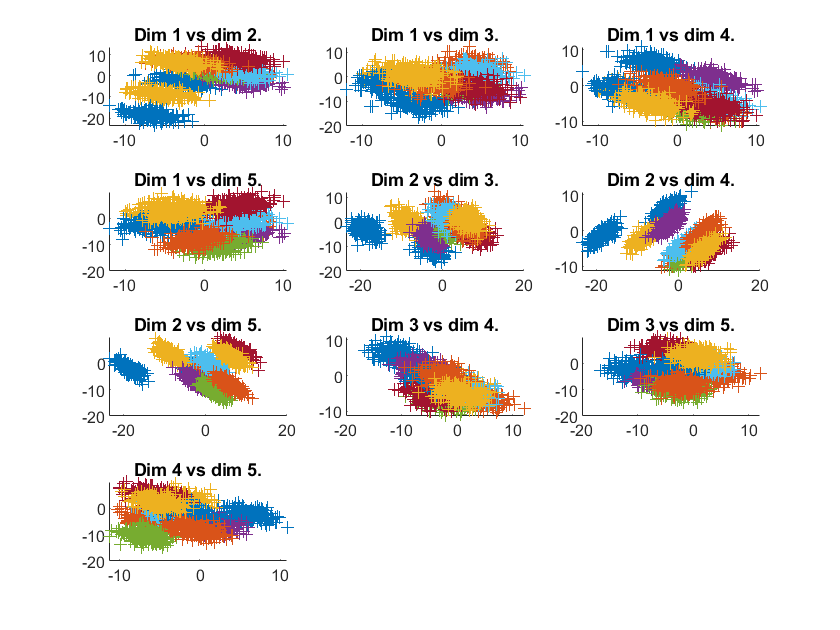

% Setup the rng for repeatability
iSetupRNG()

% Generate the data and plot it.
meanGenerator = @(x,y) Spread * randn(x,y);
[trainData,testData] = iGetTrainAndTestData(DimensionOfSpace,NumberOfCategories,NumberOfTrainSamples,NumberOfTestSamples,meanGenerator);
iPlotData(trainData)

## Training

Training the model using the standard formula and the spherification process is very similar. In the standard formula method we use the data to generate sample statistics, we then create linear boundaries using this data. 

The model is then to compute which portion of the space a given data point belongs to and to classify to that class. 

The spherification proccess starts out identically computing the sample statistics, however then a linear transform is found to spherify the sample covariance. This transform is then used to change the space the calculation occurs in. 

### Training the model using the standard formula

We train the model using the standard formula, as we do not know the original values we will have to approximate them. Which we do in the following manner. 

- We approximate $\mu_k$ as $\hat{\mu_k \;} =\mathrm{Avg}\left(X_k \right)$

- We approximate $\pi_k$ as $\hat{\pi_k } =\;\frac{N_k }{N}$, where $N$is the total number of samples in the training set and $N_k$ is the number of elements in the training set that belong to class k.

- We approximate $\Sigma$ as $\hat{\Sigma} =\frac{\Sigma_{k=1}^K \Sigma_{g_i =k} \left(x_i -\hat{\mu_k } \right){\left(x_i -\hat{\mu_k } \right)}^T }{N-K}$.

tic;
formulaModel = iTrainModel(trainData,NumberOfTrainSamples,"Formula");
timeWithSphere = toc;

### Training the model using spherification

To train the model using spherification we train as in teh standard formula, however we then create a transform on the linear space that transform the $\hat{\Sigma}$ to the identity.

This can be found using the eigenvalue decomposition of $\hat{\Sigma} ={\mathrm{UDU}}^T$. From this factorization we created the transform $f(X) = D^{-1/2}U^TX$. After we have found the $\hat{\mu_k \;}$ in the original space we transform it and use this as the $\hat{\mu_k \;}$.

tic;
spherificationModel = iTrainModel(trainData,NumberOfTrainSamples,"Spherification");
timeWithFormula = toc;

We now have two models and the time taken to generate, we will compare the ratio of time taken between the two models.

timeRatio = timeWithFormula/timeWithSphere;
disp(['Time taken using formula took ',num2str(timeRatio),' times longer than the spherification method during training.'])

Time taken using formula took 0.71742 times longer than the spherification method during training.


## Testing

We now apply the two models to test data that hasn't been seen yet. We will measure the error rate for both models and the time taken.

### Testing using the standard formula

We now test the standard formula model which is 

$G\left(x\right)={\mathrm{argmax}}_k {\hat{\delta} }_k \left(x\right)$,

for $\hat{\delta_k } \left(x\right)=x^T {\hat{\Sigma} }^{-1} \hat{\mu_k } -\frac{1}{2}{\hat{\mu_k } }^T \Sigma^{-1} \hat{\mu_k } +\log \left(\hat{\pi_k } \right)$.

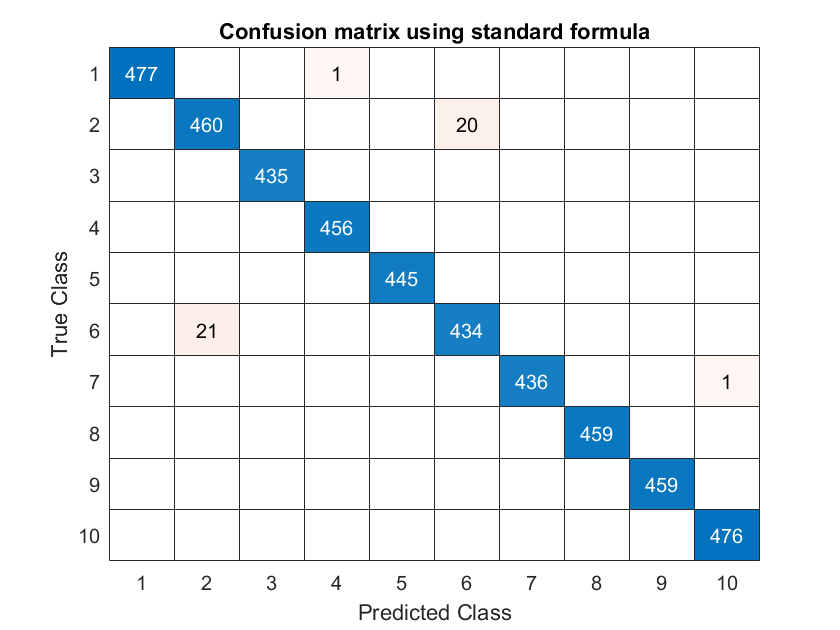

tic
testingFromFormulaClassification = iClassifyDataCells(testData,formulaModel);
timeWithFormula = toc;
confusionMatrixFormula = iGetConfusionMatrix(testingFromFormulaClassification,'Confusion matrix using standard formula');

formulaTestError = 1 - sum(diag(confusionMatrixFormula.NormalizedValues))/sum(confusionMatrixFormula.NormalizedValues,"all");
disp(['The total error from the formula method is ', num2str(formulaTestError)]);

The total error from the formula method is 0.0093886


### Testing using the spherification method

We now use the spherification model on the test data. We measure the error and display this in a confusion matrix, as well as timing the length of the calculation.

The model in the spherification method is to first map $x$ into the transformed linear space, that is we update $x$ as $f(x)$. We then classify $x$ to be in class $k$, for $k$ such that $\mu_k$ is the nearest of the $\mu_i$ upto some sampling affects of the $\pi_i$.

That is $k$ is such that $-0.5\vert\vert x - \mu_i\vert\vert ^2_2  + \log(\pi_i)$ is minimized when $i = k$.

tic;
testingFromFormulaClassification = iClassifyDataCells(testData,spherificationModel);
timeWithSphere = toc;
confusionMatrixSphere = iGetConfusionMatrix(testingFromFormulaClassification,'Confusion matrix using standard formula');

spherificationTestError = 1 - sum(diag(confusionMatrixSphere.NormalizedValues))/sum(confusionMatrixSphere.NormalizedValues,"all");
disp(['The total error from the spherification method is ', num2str(spherificationTestError)])

The total error from the spherification method is 0.0093886


## Comparison of the two methods.

First we compare the time taken for the models in the inference stage. Here we on average see that the sperification method is faster.

timeRatio = timeWithFormula/timeWithSphere;
disp(['Time taken using formula took ',num2str(timeRatio),' times longer than the spherification method during inference.'])

Time taken using formula took 1.085 times longer than the spherification method during inference.


We now compare the differences in the confusion matrices, as if these are always returning the same value, then the models agree.

mistakesAreTheSame = isequal(confusionMatrixFormula.NormalizedValues,confusionMatrixSphere.NormalizedValues);
if mistakesAreTheSame
    disp('The mistakes of the models are identical.')
else
    disp('There are discrepencies between the models.')
end

The mistakes of the models are identical.


We now see that the models are giving identical results.

It takes slightly longer to train a spherification model, due to having to calculate the eigenvalues of the training data.

There is a significant speed up at inference time using the spherification method when there are lots of classes or in a large dimension. This seems like a reasonable hypothesis as these two variables affect the size of $\Sigma$ and $\mu_k$, so will affect the computation in the formula method in the calculation of $\Sigma^{-1} \mu_k$. However, we can avoid the calculation of the inverse in the spherification method leading to a time saving.

The spherification method also has the added benefit of being more interpretable. It seems entirely reasonable that a data point should be categorized to the class with the closest mean (in the transformed space).

It follows that using the spherification method is preferable when the model is dealing with many classes or data in high dimensional space.

Helpers.ConvertMLXToPDF(mfilename);

## Functions

#### Data generation functions

function iSetupRNG()
s = RandStream("threefry");
RandStream.setGlobalStream(s);
end

function [generatedData,gaussians] = iGetDrawsFromMultipleGaussians(DimensionOfSpace,NumberOfGaussians,NumberOfSamples,meanGenerator)
gaussians     = StatisticalModels.MultipleGaussiansWithSameCovariance(DimensionOfSpace,NumberOfGaussians,meanGenerator);
categoryDraws = iGetCategoryDraws(NumberOfSamples,NumberOfGaussians);
generatedData = iGetGeneratedData(gaussians,categoryDraws);
end

function [trainData,testData] = iGetTrainAndTestData(DimensionOfSpace,NumberOfGaussians,NumberOfTrainSamples,NumberOfTestSamples,meanGenerator)
[trainData,gaussians] = iGetDrawsFromMultipleGaussians(DimensionOfSpace,NumberOfGaussians,NumberOfTrainSamples,meanGenerator);
testCategoryDraws = iGetCategoryDraws(NumberOfTestSamples,NumberOfGaussians);
testData = iGetGeneratedData(gaussians,testCategoryDraws);
end

function generatedData = iGetGeneratedData(gaussians,categoryDraws)
NumberOfCategories = size(categoryDraws,1);
generatedData = cell(1,NumberOfCategories);
for i = 1:NumberOfCategories
    currentGaussian = gaussians{i};
    numberOfCategoryDraws = categoryDraws(i);
    currentGeneratedData = mvnrnd(currentGaussian{1},currentGaussian{2},numberOfCategoryDraws);
    generatedData{i} = currentGeneratedData;
end
end
function categoryOutputs = iGetCategoryDraws(NumberOfSamples,NumberOfCategories)
dist = randi(NumberOfCategories,[NumberOfSamples,1]);
categoryOutputs = groupcounts(dist);
end

#### Training relevant functions

function Model = iTrainModel(generatedData,NumberOfSamples,type)
numberOfResponses = numel(generatedData);
Mu = zeros(numberOfResponses,size(generatedData{1},2));
Pi = zeros(numberOfResponses,1);
Sigma = 0;
for i = 1:numberOfResponses
    currentData = generatedData{i};
    currentMu = mean(currentData);
    currentPi = size(currentData,1)/NumberOfSamples;
    Mu(i,:) = currentMu;
    Pi(i,:) = currentPi;
    Sigma = Sigma + (currentData - currentMu)' * (currentData - currentMu);
end
Sigma = Sigma / (NumberOfSamples - numberOfResponses);

Model = struct('Mu', Mu, 'Pi', Pi, 'Sigma', Sigma);
if type == "Spherification"
    [~,D,W] = eig(Sigma);
    transform = (sqrt(D) \ W' );
    Mu = (transform * Mu')';
    Model.Mu = Mu;
    Model.Transform = transform;
elseif type == "Formula"
else
    error("Type is not supported.")
end
end

#### Classify relevant functions

function classification = iClassifyDataCells(dataCell,model)
if ~isfield(model,'Transform')
    classificationMethod = @iClassifyDataWithoutNorms;
else
    classificationMethod = @iClassifyData;
end
numberOfClasses = numel(dataCell);
classification = cell(1,numberOfClasses);
for i = 1:numberOfClasses
    data = dataCell{i};
    currentClassification = classificationMethod(data,model);
    classification{i} = currentClassification;
end
end

function classification = iClassifyDataWithoutNorms(data,model)
Mu = model.Mu;
Pi = model.Pi;
Sigma = model.Sigma;
otherData = data * ( Sigma \ Mu') - 0.5 * diag(Mu * ( Sigma \ Mu'))' + log(Pi)';
[~,classification] = max(otherData,[],2);
end

function classification = iClassifyData(data,model)
Mu = model.Mu;
Pi = model.Pi;
transform = model.Transform;
transformedData = (transform * data')';
otherData = transformedData * (Mu)' - 0.5 * diag(Mu * ( Mu'))' + log(Pi)';
[~,classification] = max(otherData,[],2);
end

#### Plotting and error relevant function 

function iPlotData(generatedData)
tiledlayout('flow',"TileSpacing","loose")
numberOfDimensions = size(generatedData{1},2);
for i = 1:numberOfDimensions
    for j = i + 1: numberOfDimensions
        nexttile
        iGenerate2DPlot(generatedData,i,j)
    end
end
end

function iGenerate2DPlot(dataCell,dimension1,dimension2)
hold on
numberOfResponses = numel(dataCell);
for i = 1:numberOfResponses
    currentData = dataCell{i};
    plot(currentData(:,dimension1),currentData(:,dimension2),"+");
end
title(['Dim ', num2str(dimension1),' vs dim ', num2str(dimension2),'.'])
hold off
end

function confusionMatrix = iGetConfusionMatrix(classification,title)
numberOfClasses = numel(classification);
confusionMatrix = zeros(numberOfClasses);
for i = 1:numberOfClasses
    for j = 1:numberOfClasses
        confusionMatrix(i,j) = sum(classification{i} == j);
    end
end
f = figure;
confusionMatrix = confusionchart(confusionMatrix,'Title',title);
end